clear

load('input.mat')

[lambda, llh] = hmmEM(data, opt.lambda, opt.maxIter, opt.tol);

Smoother took 2.27 seconds on interation 1 
Baum Welch took 5.09 seconds on interation 1 
Smoother took 1.89 seconds on interation 2 
Baum Welch took 4.92 seconds on interation 2 
Smoother took 1.51 seconds on interation 3 
Baum Welch took 4.21 seconds on interation 3 
Smoother took 1.42 seconds on interation 4 
Baum Welch took 4.07 seconds on interation 4 
Smoother took 1.47 seconds on interation 5 
Baum Welch took 4.15 seconds on interation 5 
Smoother took 1.27 seconds on interation 6 
Baum Welch took 4.15 seconds on interation 6 
Smoother took 1.34 seconds on interation 7 
Baum Welch took 4.11 seconds on interation 7 
Smoother took 1.36 seconds on interation 8 
Baum Welch took 3.74 seconds on interation 8 
Smoother took 1.58 seconds on interation 9 
Baum Welch took 4.21 seconds on interation 9 
Smoother took 1.28 seconds on interation 10 
Baum Welch took 3.85 seconds on interation 10 


[viterbi, logP] = hmmViterbi(data,lambda);

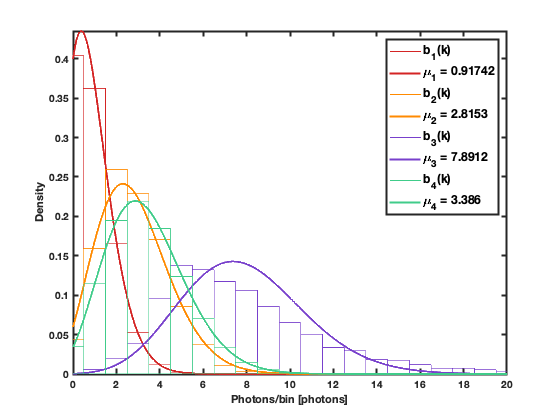

colors = [0.83 0.14 0.14
             1.00 0.54 0.00
             0.47 0.25 0.80
             0.25 0.80 0.54];
         
%plot distributions
figure
LegHandles = [];
LegText = {};
hold on
x_max = 50;
res = 0.01;
d = 0:1:x_max-1;
%continuous version of poisson, for plotting only
k = 0:res:x_max-1;
poiss_cont = @(lam)(lam.^k.*exp(-lam)./gamma(k+1));

for i = 1:size(lambda.B,1)
    %plot bar
    LegHandles(end+1) = bar(d,lambda.B(i,1:x_max),'hist');
    set(LegHandles(end),'FaceColor','none','EdgeColor',colors(i,:),...
        'LineStyle','-', 'LineWidth',1);
    LegText{end+1} = ['b_',num2str(i),'(k)'];
    
    %calculate and plot fit
    lam_temp = sum((0:1:size(lambda.B,2)-1).*lambda.B(i,:)); %mean definition of poisson
    LegHandles(end+1) = plot(k,poiss_cont(lam_temp),'Color',colors(i,:));
    LegText{end+1} = ['\mu_',num2str(i),' = ',num2str(lam_temp)];
end

xlabel('Photons/bin [photons]');
ylabel('Density')
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 12, 'Location', 'northeast');
axis tight
set(gca,'xlim',[0,20])